# Optimization of the single feeding trajectory

**Manipulated variables**

- `u = Q_in [L/h]`: feed rate

**Measured disturbance**

- `none`

**State variables**

- `x1 = V [L]`: liquid volume in the reactor

- `x2 = Xv [cell/L]`: viable cell density

- `x3 = Xt [cell/L]`: total cell density 

- `x4 = Gl`c` [mM]`: Glucose concentration

- `x5 = Gln [mM]`: Glutamine concentration

- `x6 = Lac [mM]`: Lactate concentration

- `x7 = Amm [mM]`: Ammonia concentration

- `x8 = mAb_ext [mg/L]`: extracellular mAb concentration

- `x9 = mRNA_Hc [molecule/cell]:` Intracellular amount of mRNA for heavy chains

- `x10 = mRNA_Lc [molecule/cell]` `:` Intracellular amount of mRNA for light chains

- `x11 = Hc [molecule/cell]:` Intracellular amount of heavy chains

- `x12 = Lc [molecule/cell]:` Intracellular amount of light chains

- `x13 = Hc2 [molecule/cell]:` Intracellular amount of heavy chain dimers

- `x14 = Hc2Lc [molecule/cell]:` Intracellular amount of assemblies of heavy and light chains

- `x15 = mAb_ER [molecule/cell]:` mAb amount in the endoplasmic reticulum

- `x16 = mAb_gol [molecule/cell]:` mAb amount in the golgi apparatus

**Output variables: the same as the state variables**

**The goal:** to maximize the final mAb mass (`x1(Tf)*x8(Tf)`). 

**Contraints:** 

- Upper bound on the liquid volume (x`1`) 

## Specify the initial states.

V0 = 0.2;       % [L]
Xv0 = 2E+8;     % [cell]
Xt0 = 2E+8;     % [cell]
Glc0 = 25.1;    % [mM]
Gln0 = 5.01;    % [mM]
Lac0 = 0;       % [mM]
Amm0 = 0;       % [mM]
mAb_ext0 = 100; % [mg/L]
mRNA_Hc0 = 0;
mRNA_Lc0 = 0;
Hc0 = 0;
Lc0 = 0;
Hc2_0 = 0;
Hc2Lc_0 = 0;
mAb_ER0 = 0;
mAb_gol0 = 0;

x0 = [V0; Xv0; Xt0; Glc0; Gln0; Lac0; Amm0; ...
        mAb_ext0; mRNA_Hc0; mRNA_Lc0; Hc0; Lc0; Hc2_0; Hc2Lc_0; mAb_ER0; mAb_gol0 ...
     ];

Specify the nominal inputs.

u0 = 0;

## Design nonlinear MPC with the true model

Create a nonlinear MPC object with 16 states, 16 outputs, 1 manipulated variables, and NO measured disturbance.

nlmpcTrue = nlmpc(16,16,1); % nlpmc object

標準のコスト関数では、MV が OV より少ないため、既定で 1 つ以上の OV に 0 の重みが割り当てられます。


Given the expected batch duration `Tf`, choose the controller sample time `Ts` and prediction horizon.

Tf = 168;   % [h] process duration
Ts = 12;    % [h] prediction model sample time
N = Tf/Ts;  % [step] prediction horizon
nlmpcTrue.Ts = Ts;
nlmpcTrue.PredictionHorizon = N;
% nlmpcobj.ControlHorizon = N;
nlmpcTrue.ControlHorizon = (24/Ts)*ones(7,1);
nlmpcTrue.Optimization.MVInterpolationOrder = 1;

### Specify the nonlinear state function in the controller

The function `fedbatch_StateFcnDT` converts the continuous-time model to discrete time using a multi-step Forward Euler integration formula.

STATEFCN = @Kontoravdi2010StateFcn;
nlmpcTrue.Model.StateFcn = @(x,u) discretizeStateFcn(x,u,Ts,STATEFCN);
nlmpcTrue.Model.OutputFcn = @(x,u) x;

% the nonlinear state function is for discrete-time models.
nlmpcTrue.Model.IsContinuousTime = false;

### Specify the bounds for input/output variables

Specify the bounds for a manipurated input variable (feed rate`)`.

% states
stateName = {'V','Xv','Xt','Glc','Gln','Lac','Amm','mAb_ext', ...
                'mRNA_Hc', 'mRNA_Lc', 'Hc', 'Lc', 'Hc2', 'Hc2Lc', ...
                'mAb_ER', 'mAb_gol' ...
            };
stateUnit = {'L', 'cell/L', 'cell/L', 'mM', 'mM', 'mM', 'mM', 'mg/L', ...
                'molecule/cell', 'molecule/cell', 'molecule/cell', 'molecule/cell', ...
                'molecule/cell', 'molecule/cell', 'molecule/cell', 'molecule/cell' ...
            };
stateScaleFactor = [0.04 2.5E+9 2.5E+9 25 5 25 5 2500 ...
                        5E+6 5E+6 5E+6 5E+7 1E+6 1E+6 5E+7 2E+8 ...
                   ];

for stateIdx = 1:16
    nlmpcTrue.States(stateIdx).Name = stateName{stateIdx};
    nlmpcTrue.States(stateIdx).ScaleFactor = stateScaleFactor(stateIdx);
    nlmpcTrue.States(stateIdx).Units = stateUnit{stateIdx};
end

% manipulated variable
nlmpcTrue.MV.Name = 'Q_in';
nlmpcTrue.MV.ScaleFactor = 0.04/168;
nlmpcTrue.MV.Units = 'L/h';
nlmpcTrue.MV.Min = 0;
nlmpcTrue.MV.MinECR = 0;

% output variables
for outputIdx = 1:16
    nlmpcTrue.OV(outputIdx).Name = nlmpcTrue.States(outputIdx).Name;
    nlmpcTrue.OV(outputIdx).ScaleFactor = nlmpcTrue.States(outputIdx).ScaleFactor;
    nlmpcTrue.OV(outputIdx).Units = nlmpcTrue.States(outputIdx).Units;
end

% total feed limit
nlmpcTrue.OV(1).Max = 0.24;
nlmpcTrue.OV(1).MaxECR = 0.2;

% weight for the slack variable
rho_e = 1E-3; 

### Specify the custom cost function

nlmpcTrue.Optimization.CustomCostFcn = @(X,U,e,data) 1/(X(end,8)*X(end,1)) + rho_e*e^2;  % changed from 1E-4 % mAb*V [mg]
nlmpcTrue.Optimization.ReplaceStandardCost = true;

### Specify the solver option

nlmpcTrue.Optimization.SolverOptions.Display = 'iter-detailed';

### Validate the nlmpc object

validateFcns(nlmpcTrue, x0, u0);

Model.StateFcn is OK.
Model.OutputFcn is OK.
Optimization.CustomCostFcn is OK.
ユーザー指定のモデル、コストおよび制約関数の解析が完了しました。


## Off-line optimization of the feeding trajectory

Find the optimal trajectories for the manipulated variables such that production of mAb is maximized at the end of the fed-batch process. To do so, use the `nlmpcmove` function.

timenow = datestr(datetime('now'));
fprintf('Optimization started at %s',timenow);

Optimization started at 05-Dec-2022 23:26:54

tic
[~,~,Info_true] = nlmpcmove(nlmpcTrue,x0,u0)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    5.000000e-02     2.216e+00     1.000e+00     0.000e+00     1.250e+00  
    1           3    4.519511e-02     1.460e+00     1.000e+00     4.929e+01     5.309e+03  
    2           5    5.234777e-02     3.600e-01     1.000e+00     1.212e+01     3.033e+02  
    3           7    5.276680e-02     7.000e-03     1.000e+00     1.576e+00     2.063e+01  
    4           9    5.270718e-02     1.673e-06     1.000e+00     2.179e-02     2.846e-01  
    5          11    5.259118e-02     2.212e-07     1.000e+00     1.598e-02     2.947e-01  
    6          13    5.215235e-02     2.390e-06     1.000e+00     6.099e-02     2.946e-01  
    7          15    5.167036e-02     4.824e-06     1.000e+00     7.225e-02     2.946e-01  
    8          17    5.082257e-02     1.420e-05     1.000e+00     1.279e-01     2.

Info_true = フィールドをもつ struct :
         MVopt: [15×1 double]
          Xopt: [15×16 double]
          Yopt: [15×16 double]
          Topt: [15×1 double]
         Slack: 0.0031
      ExitFlag: 1
    Iterations: 149
          Cost: 9.4206e-04


toc

経過時間は 35.319645 秒です。


printFinalmAb(Info_true);

Final liquid volume: 0.240025 L
Final mAb conc: 4422.5 mg/L
Final mAb amount: 1061.51 mg


## Simulate the optimized feeding trajectory

The discretized model, which the nonlinear MPC has uses a simple Euler integration, which could be inaccurate. To check this, integrate the model using the `ode15s` command for the optimized feeding trajectory. 

Final liquid volume: 0.240025 L
Final mAb conc: 4425.12 mg/L
Final mAb amount: 1062.14 mg


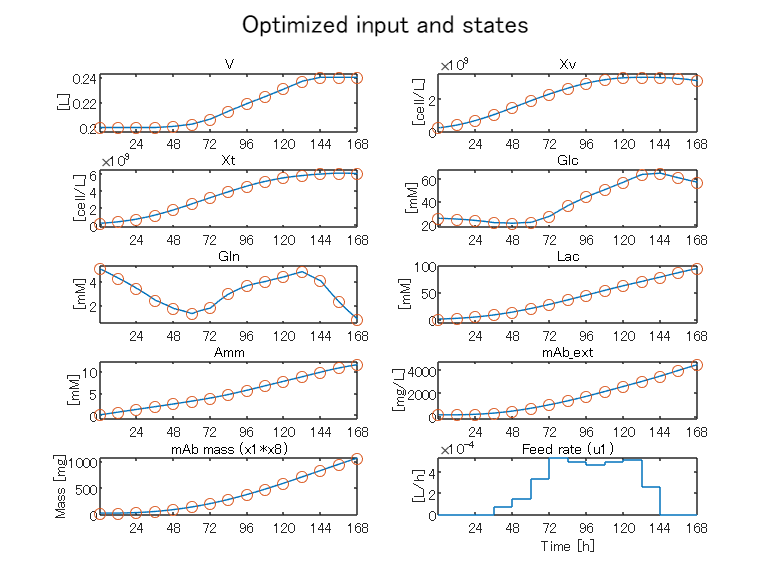

simTrueSFModel(Info_true,Ts,x0);

## Plant-model mismatch disturbs off-line optimization

Specify a state function with parameter errors to a new nlmpc object.

nlmpcTrue_error = nlmpcTrue;
STATEFCN = @Kontoravdi2010StateFcnError;
nlmpcTrue_error.Model.StateFcn = @(x,u) discretizeStateFcn(x,u,Ts,STATEFCN);

Start optimization.

timenow = datestr(datetime('now'));
fprintf('Optimization started at %s',timenow);

Optimization started at 05-Dec-2022 23:27:33

tic
[~,~,Info_true_error] = nlmpcmove(nlmpcTrue_error,x0,u0)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    5.000000e-02     2.216e+00     1.000e+00     0.000e+00     1.250e+00  
    1           3    9.843253e-03     6.584e-01     1.000e+00     3.476e+01     2.175e+03  
    2           5    7.356035e-03     3.600e-01     1.000e+00     8.970e+00     7.142e+01  
    3           7    8.021044e-03     7.000e-03     1.000e+00     1.591e+00     2.187e+01  
    4           9    8.015178e-03     1.673e-06     1.000e+00     2.067e-02     1.410e-02  
    5          11    8.012363e-03     7.565e-09     1.000e+00     1.841e-03     1.410e-02  
    6          13    7.998901e-03     1.072e-07     1.000e+00     9.026e-03     1.410e-02  
    7          15    7.932230e-03     2.244e-06     1.000e+00     4.502e-02     1.410e-02  
    8          17    7.779274e-03     1.166e-05     1.000e+00     1.055e-01     1.

Info_true_error = フィールドをもつ struct :
         MVopt: [15×1 double]
          Xopt: [15×16 double]
          Yopt: [15×16 double]
          Topt: [15×1 double]
         Slack: 5.9394e-04
      ExitFlag: 1
    Iterations: 138
          Cost: 0.0018


toc

経過時間は 33.290669 秒です。


printFinalmAb(Info_true_error);

Final liquid volume: 0.240005 L
Final mAb conc: 2324.44 mg/L
Final mAb amount: 557.876 mg


Simulate the true model with the feeding trajectory optimized in the presense of the plant-model mismatch.

Final liquid volume: 0.240005 L
Final mAb conc: 3822.81 mg/L
Final mAb amount: 917.492 mg


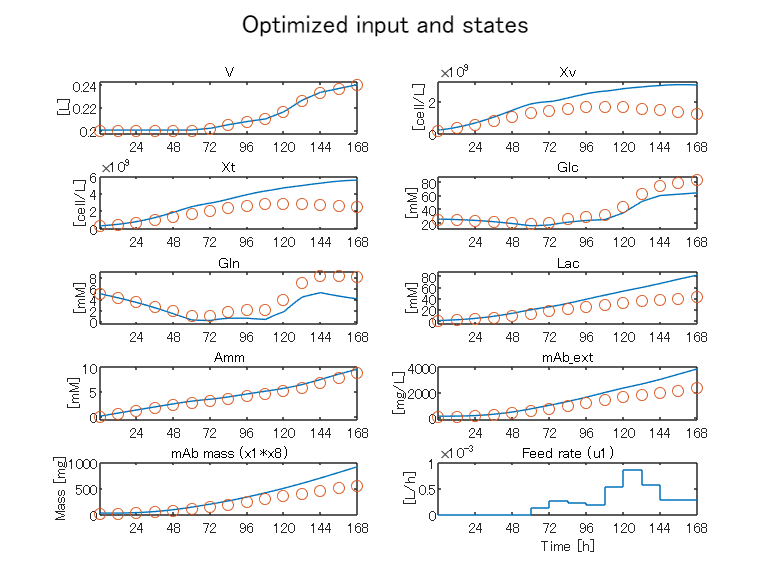

simTrueSFModel(Info_true_error,Ts,x0);

## Design nonlinear MPC with the reduced model

Create a nonlinear MPC object with 8 states, 8 outputs, 1 manipulated variables, and NO measured disturbance.

nlmpcReduced = nlmpc(8,8,1); % nlpmc object

標準のコスト関数では、MV が OV より少ないため、既定で 1 つ以上の OV に 0 の重みが割り当てられます。


Given the expected batch duration `Tf`, choose the controller sample time `Ts` and prediction horizon.

Tf = 168;   % [h] process duration
Ts = 12;    % [h] prediction model sample time
N = Tf/Ts;  % [step] prediction horizon
nlmpcReduced.Ts = Ts;
nlmpcReduced.PredictionHorizon = N;
% nlmpcobj.ControlHorizon = N;
nlmpcReduced.ControlHorizon = (24/Ts)*ones(7,1);
nlmpcReduced.Optimization.MVInterpolationOrder = 1;

### Specify the nonlinear state function in the controller

The function `fedbatch_StateFcnDT` converts the continuous-time model to discrete time using a multi-step Forward Euler integration formula.

STATEFCN = @Kontoravdi2010RStateFcn

STATEFCN = 値をもつ function_handle :
    @Kontoravdi2010RStateFcn


nlmpcReduced.Model.StateFcn = @(x,u) discretizeStateFcn(x,u,Ts,STATEFCN);
nlmpcReduced.Model.OutputFcn = @(x,u) x;

% the nonlinear state function is for discrete-time models.
nlmpcReduced.Model.IsContinuousTime = false;

### Specify the bounds for input/output variables

Specify the bounds for a manipurated input variable (feed rate`)`.

% states
stateName = {'V','Xv','Xt','Glc','Gln','Lac','Amm','mAb_ext', ...
                'mRNA_Hc', 'mRNA_Lc', 'Hc', 'Lc', 'Hc2', 'Hc2Lc', ...
                'mAb_ER', 'mAb_gol' ...
            };
stateUnit = {'L', 'cell/L', 'cell/L', 'mM', 'mM', 'mM', 'mM', 'mg/L', ...
                'molecule/cell', 'molecule/cell', 'molecule/cell', 'molecule/cell', ...
                'molecule/cell', 'molecule/cell', 'molecule/cell', 'molecule/cell' ...
            };
stateScaleFactor = [0.04 2.5E+9 2.5E+9 25 5 25 5 2500 ...
                        5E+6 5E+6 5E+6 5E+7 1E+6 1E+6 5E+7 2E+8 ...
                   ];

for stateIdx = 1:8
    nlmpcReduced.States(stateIdx).Name = stateName{stateIdx};
    nlmpcReduced.States(stateIdx).ScaleFactor = stateScaleFactor(stateIdx);
    nlmpcReduced.States(stateIdx).Units = stateUnit{stateIdx};
end

% manipulated variable
nlmpcReduced.MV.Name = 'Q_in';
nlmpcReduced.MV.ScaleFactor = 0.04/168;
nlmpcReduced.MV.Units = 'L/h';
nlmpcReduced.MV.Min = 0;
nlmpcReduced.MV.MinECR = 0;

% output variables
for outputIdx = 1:8
    nlmpcReduced.OV(outputIdx).Name = nlmpcReduced.States(outputIdx).Name;
    nlmpcReduced.OV(outputIdx).ScaleFactor = nlmpcReduced.States(outputIdx).ScaleFactor;
    nlmpcReduced.OV(outputIdx).Units = nlmpcReduced.States(outputIdx).Units;
end

% total feed limit
nlmpcReduced.OV(1).Max = 0.24;
nlmpcReduced.OV(1).MaxECR = 0.2;

% weight for the slack variable
rho_e = 1E-3; 

### Specify the custom cost function

nlmpcReduced.Optimization.CustomCostFcn = @(X,U,e,data) 1/(X(end,8)*X(end,1)) + rho_e*e^2;  % changed from 1E-4 % mAb*V [mg]
nlmpcReduced.Optimization.ReplaceStandardCost = true;

### Specify the solver option

nlmpcReduced.Optimization.SolverOptions.Display = 'iter-detailed';

### Validate the nlmpc object

validateFcns(nlmpcReduced, x0(1:8), u0);

Model.StateFcn is OK.
Model.OutputFcn is OK.
Optimization.CustomCostFcn is OK.
ユーザー指定のモデル、コストおよび制約関数の解析が完了しました。


Start optimization.

timenow = datestr(datetime('now'));
fprintf('Optimization started at %s',timenow);

Optimization started at 05-Dec-2022 23:28:36

tic
[~,~,Info_reduced] = nlmpcmove(nlmpcReduced,x0(1:8),u0)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    5.000000e-02     1.528e-01     1.000e+00     0.000e+00     1.250e+00  
    1           4    3.552659e-02     2.286e-01     1.000e+00     3.367e+01     3.587e+03  
    2           6    3.267772e-02     7.109e-03     1.000e+00     2.578e+00     1.215e+00  
    3           8    3.262121e-02     3.051e-06     1.000e+00     5.296e-02     6.950e-01  
    4          10    3.249123e-02     6.979e-09     1.000e+00     1.196e-02     1.062e-01  
    5          12    3.186319e-02     2.083e-08     1.000e+00     5.797e-02     1.062e-01  
    6          14    2.901636e-02     6.046e-08     1.000e+00     2.705e-01     1.062e-01  
    7          16    2.563928e-02     8.572e-09     1.000e+00     3.405e-01     1.062e-01  
    8          18    2.560243e-02     1.496e-07     1.000e+00     6.328e-03     1.

Info_reduced = フィールドをもつ struct :
         MVopt: [15×1 double]
          Xopt: [15×8 double]
          Yopt: [15×8 double]
          Topt: [15×1 double]
         Slack: 0.0032
      ExitFlag: 1
    Iterations: 168
          Cost: 9.7055e-04


toc

経過時間は 15.723760 秒です。


printFinalmAb(Info_reduced);

Final liquid volume: 0.240026 L
Final mAb conc: 4292.66 mg/L
Final mAb amount: 1030.35 mg


Final liquid volume: 0.240026 L
Final mAb conc: 4426.52 mg/L
Final mAb amount: 1062.48 mg


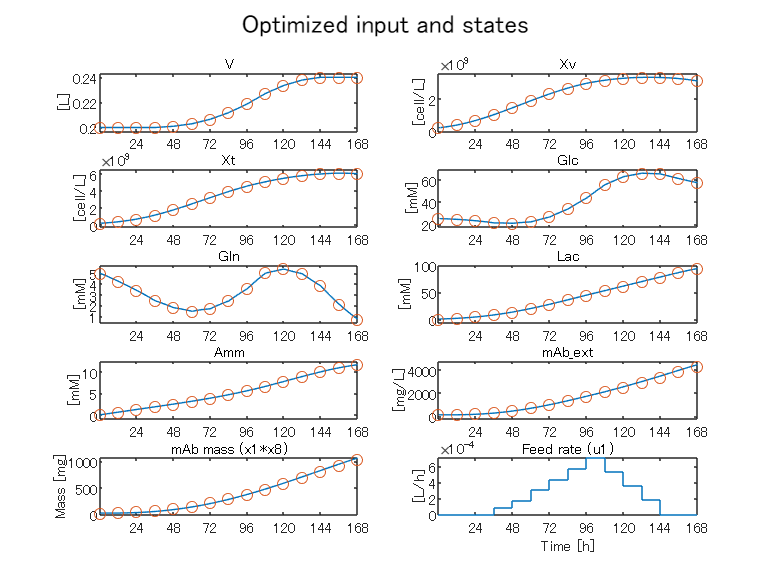

simTrueSFModel(Info_reduced,Ts,x0);

## Plant-model mismatch disturbs off-line optimization

nlmpcReduced_error = nlmpcReduced;
STATEFCN = @Kontoravdi2010RStateFcnError

STATEFCN = 値をもつ function_handle :
    @Kontoravdi2010RStateFcnError


nlmpcReduced_error.Model.StateFcn = @(x,u) discretizeStateFcn(x,u,Ts,STATEFCN);
validateFcns(nlmpcReduced_error, x0(1:8), u0);

Model.StateFcn is OK.
Model.OutputFcn is OK.
Optimization.CustomCostFcn is OK.
ユーザー指定のモデル、コストおよび制約関数の解析が完了しました。


Start optimization.

timenow = datestr(datetime('now'));
fprintf('Optimization started at %s',timenow);

Optimization started at 05-Dec-2022 23:28:53

tic
[~,~,Info_reduced_error] = nlmpcmove(nlmpcReduced_error,x0(1:8),u0)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    5.000000e-02     1.464e-01     1.000e+00     0.000e+00     1.250e+00  
    1           4    2.501419e-03     3.343e-01     1.000e+00     1.619e+01     9.295e+02  
    2           6    3.964956e-03     1.312e-02     1.000e+00     2.641e+00     6.159e+00  
    3           8    4.011699e-03     2.125e-05     1.000e+00     8.251e-02     4.669e-01  
    4          10    4.011704e-03     1.235e-10     1.000e+00     1.818e-04     3.521e-03  
    5          12    4.011576e-03     1.106e-09     1.000e+00     6.724e-04     3.474e-03  
    6          14    4.010956e-03     5.964e-09     1.000e+00     3.339e-03     3.475e-03  
    7          16    4.008251e-03     3.960e-08     1.000e+00     1.613e-02     3.475e-03  
    8          18    4.002364e-03     3.172e-07     1.000e+00     6.397e-02     3.

Info_reduced_error = フィールドをもつ struct :
         MVopt: [15×1 double]
          Xopt: [15×8 double]
          Yopt: [15×8 double]
          Topt: [15×1 double]
         Slack: 5.0438e-04
      ExitFlag: 1
    Iterations: 120
          Cost: 0.0018


toc

経過時間は 10.022940 秒です。


printFinalmAb(Info_reduced_error);

Final liquid volume: 0.240004 L
Final mAb conc: 2287.31 mg/L
Final mAb amount: 548.963 mg


Final liquid volume: 0.240004 L
Final mAb conc: 3833.95 mg/L
Final mAb amount: 920.163 mg


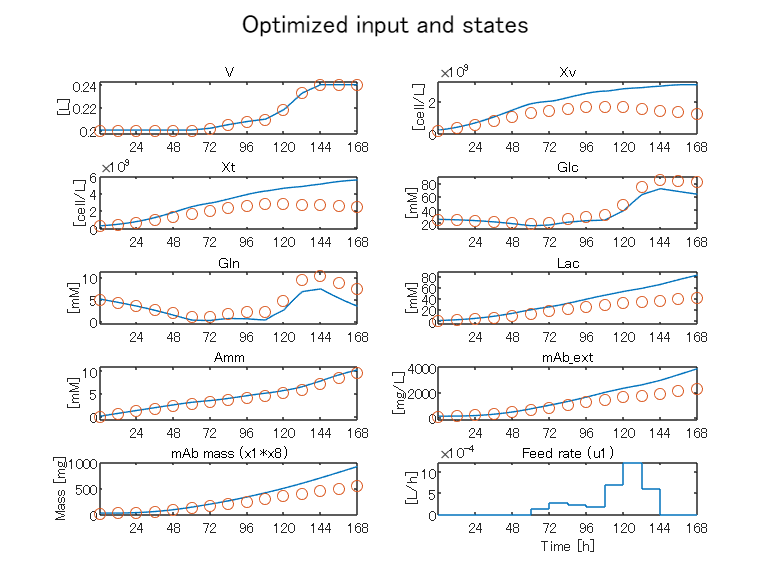

simTrueSFModel(Info_reduced_error,Ts,x0);

## On-line reoptimization in the presence of the plant-model mismatch

nlmpcReduced_error.Model.StateFcn = @(x,u,N) discretizeStateFcn(x,u,Ts,STATEFCN);
nlmpcReduced_error.Model.NumberOfParameters = 1;
nlmpcReduced_error.Model.OutputFcn = @(x,u,N) x;
nlmpcReduced_error.Optimization.CustomCostFcn = @(X,U,e,data,N) 1/(X(1+N,8)*X(1+N,1)) + rho_e*e^2;
validateFcns(nlmpcReduced_error, x0(1:8), u0, [], {N});

Model.StateFcn is OK.
Model.OutputFcn is OK.
Optimization.CustomCostFcn is OK.
ユーザー指定のモデル、コストおよび制約関数の解析が完了しました。


Open the Simulink model.

mdl = 'MPC_reduced';
open_system(mdl)

To use the optional parameter in the prediction model, the model has a Simulink Bus block connected to the `params` input port of the Nonlinear MPC Controller block. To configure this bus block to use the `N` parameter, create a Bus object in the MATLAB workspace, and configure the Bus Creator block to use this object. Name the Bus object `'myBusObject'`.

createParameterBus(nlmpcReduced_error,[mdl '/Nonlinear MPC'],'myBusObject',{N});

Simulink バス オブジェクト "myBusObject" が MATLAB ワークスペースで作成され、Bus Creator ブロック "MPC_reduced/Nonlinear MPC" がこのオブジェクトを使用するように構成されています。


timenow = datestr(datetime('now'));
fprintf('Optimization started at %s',timenow);

Optimization started at 05-Dec-2022 23:29:23

tic
simout = sim(mdl);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    5.000000e-02     1.464e-01     1.000e+00     0.000e+00     1.250e+00  
    1           4    2.501419e-03     3.343e-01     1.000e+00     1.619e+01     9.295e+02  
    2           6    3.964956e-03     1.312e-02     1.000e+00     2.641e+00     6.159e+00  
    3           8    4.011699e-03     2.125e-05     1.000e+00     8.251e-02     4.669e-01  
    4          10    4.011704e-03     1.235e-10     1.000e+00     1.818e-04     3.521e-03  
    5          12    4.011576e-03     1.106e-09     1.000e+00     6.724e-04     3.474e-03  
    6          14    4.010956e-03     5.964e-09     1.000e+00     3.339e-03     3.475e-03  
    7          16    4.008251e-03     3.960e-08     1.000e+00     1.613e-02     3.475e-03  
    8          18    4.002364e-03     3.172e-07     1.000e+00     6.397e-02     3.

toc

経過時間は 66.808195 秒です。


Final liquid volume: 0.239276 L
Final mAb conc: 4387.73 mg/L
Final mAb amount: 1049.88 mg


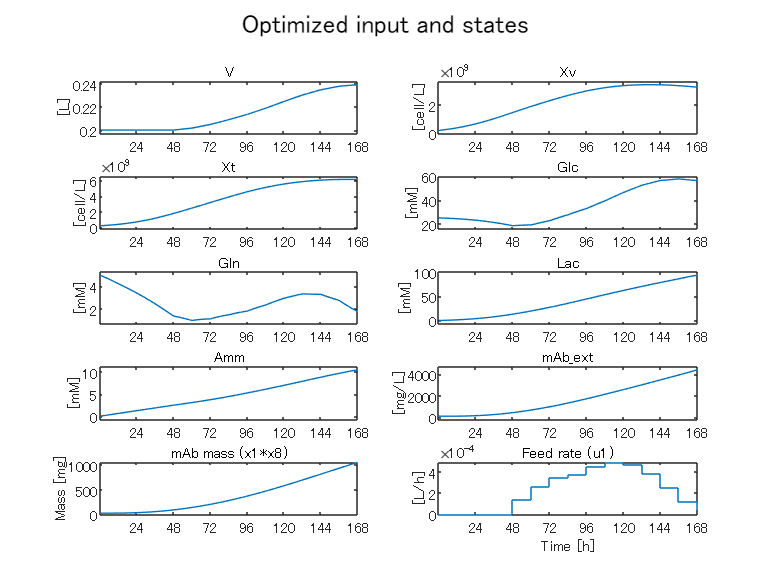

plotSimulinkLog(simout);